% compare_pinv_vs_ridge_failure.m
clear; clc; close all;

%% 1) Геометрия «идеального» тетраэдра (нормировка на √3)
B = [  1,  1, -1, -1;
       1, -1,  1, -1;
       1, -1, -1,  1 ] / sqrt(3);

% Отказ rw1, оставшиеся — rw2,rw3,rw4
active = [false, true, true, true];
B_act  = B(:, active);    % 3×3

%% 2) Внешний постоянный момент (Н·м)
M_dist = [2e-3; 1e-3; 0];

%% 3) Параметры аллокаторов и интеграции
tau_max = Inf;      % без насыщения по моменту
Jr      = 1e-3;     % инерция маховика
lam     = 1e-3;     % гребневой параметр (~σ_min(B_act))

t       = linspace(0,500,1001);
dt      = t(2)-t(1);

%% 4) Однократный расчёт τ (одинаков для всего t)
% --- pinv ---
tau_p_act = pinv(B_act)*M_dist;
tau_p_full = zeros(4,1);
tau_p_full(active) = tau_p_act;

% --- ridge-Tikhonov ---
tau_r_act = (B_act'*B_act + lam^2*eye(3)) \ (B_act'*M_dist);
tau_r_full = zeros(4,1);
tau_r_full(active) = tau_r_act;

fprintf('tau_pinv = [%.4f  %.4f  %.4f  %.4f]\\n', tau_p_full);

tau_pinv = [0.0000  -0.0009  -0.0017  -0.0026]\n

fprintf('tau_ridge= [%.4f  %.4f  %.4f  %.4f]\\n', tau_r_full);

tau_ridge= [0.0000  -0.0009  -0.0017  -0.0026]\n

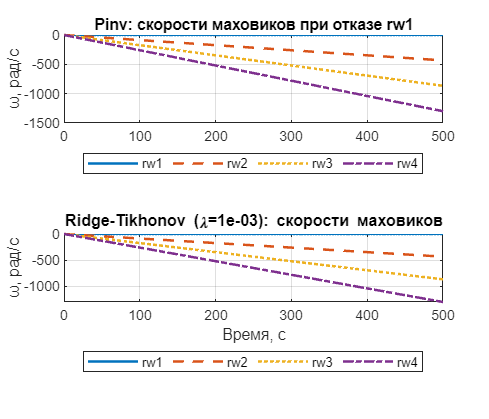


%% 5) Интегрируем скорости маховиков
omega_pinv  = zeros(4,numel(t));
omega_ridge = zeros(4,numel(t));
for k=2:numel(t)
    omega_pinv(:,k)  = omega_pinv(:,k-1)  + (tau_p_full  / Jr) * dt;
    omega_ridge(:,k) = omega_ridge(:,k-1) + (tau_r_full / Jr) * dt;
end

%% 6) Построение графиков
figure('Position',[200 200 700 600]);

subplot(2,1,1);
plot(t,omega_pinv(1,:),'-','LineWidth',1.5); hold on;
plot(t,omega_pinv(2,:),'--','LineWidth',1.5);
plot(t,omega_pinv(3,:),':','LineWidth',1.5);
plot(t,omega_pinv(4,:),'-.','LineWidth',1.5);
grid on;
ylabel('ω, рад/с');
title('Pinv: скорости маховиков при отказе rw1');
legend('rw1','rw2','rw3','rw4','Location','southoutside','Orientation','horizontal');

subplot(2,1,2);
plot(t,omega_ridge(1,:),'-','LineWidth',1.5); hold on;
plot(t,omega_ridge(2,:),'--','LineWidth',1.5);
plot(t,omega_ridge(3,:),':','LineWidth',1.5);
plot(t,omega_ridge(4,:),'-.','LineWidth',1.5);
grid on;
xlabel('Время, с'); ylabel('ω, рад/с');
title(sprintf('Ridge-Tikhonov (\\lambda=%.0e): скорости маховиков', lam));
legend('rw1','rw2','rw3','rw4','Location','southoutside','Orientation','horizontal');


omega_pinv-omega_ridge

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   